# Show Productive Diagram demo

Use ShowDiagramFP function to show the productive diagram and the fuel-product tables

#### **Read Data Model**

model=ReadDataModel('tgas_model.xlsx');

#### **Build Diagram FP**

options.State='Reference';
res=ShowDiagramFP(model,options);

#### Show Results

printResults(res);

 FP Table (kW)

 Key         COMB      COMP      GTRB      HRSG      STCK       ENV     Total
------------------------------------------------------------------------------
 COMB         0.0       0.0   15146.5    7737.1     594.5       0.0   23478.0
 COMP         0.0       0.0    6136.5    3134.6     240.8       0.0    9512.0
 GTRB         0.0   10225.0       0.0       0.0       0.0   10000.0   20225.0
 HRSG         0.0       0.0       0.0       0.0       0.0    7168.0    7168.0
 STCK         0.0       0.0       0.0       0.0       0.0     835.3     835.3
 ENV      36620.0       0.0       0.0       0.0       0.0       0.0   36620.0
------------------------------------------------------------------------------
 Total    36620.0   10225.0   21283.0   10871.7     835.3   18003.3          


FP Adjacency Table

  Id  Key  Source  Target   Value(kW)
--------------------------------------
   1  E1   IN1     COMB       36620.0
   2  E2   GTRB    COMP       10225.0
   3  E3   COMB    GTRB    

#### Plot Diagram FP

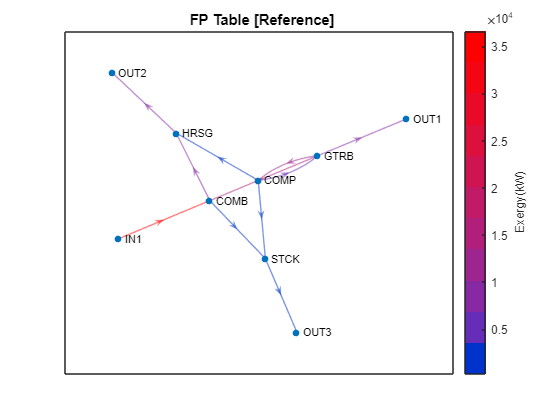

res.showDiagramFP;